# Quantum Graph Routines in MATLAB

## MATLAB graph basics

MATLAB has built-in data types for graphs and directed graphs. We have used the latter as the basic buliding block for a set of routines (listed in accompanying `Contents.m` file) for computing with linear and nonlinear quantum graphs: directed graphs which solve PDE's on the edges, subject to some kind of boundary condition or matching condition at the vertices.

We first show how to create and display a graph:

sources=[1 1 2 1 3];
targets=[1 2 2 3 2];
G = graph(sources,targets)

G =   graph with properties:

    Edges: [5×1 table]
    Nodes: [3×0 table]


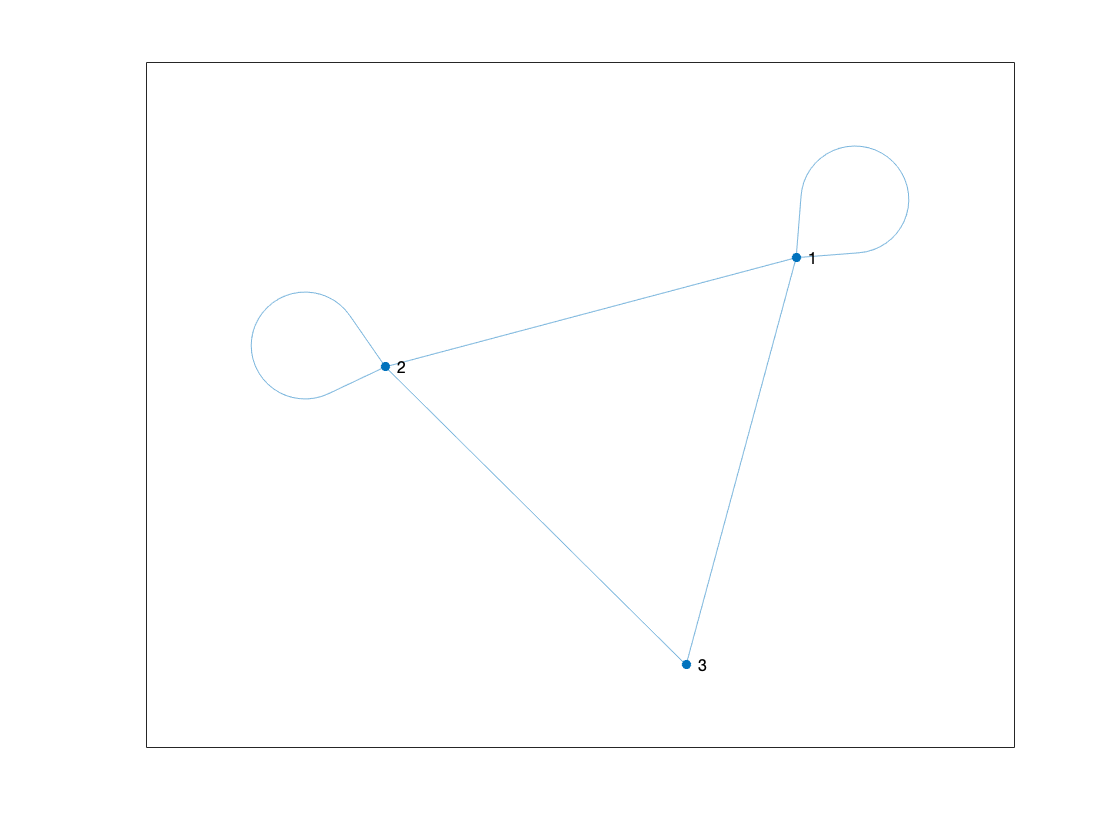

plot(G)

The input consists of two integer-valued vectors of equal length, from which the graph is built. Each element of each list give the beginning and ending vertex of the corresponding edge. MATLAB refers to these as the source and target nodes of the given edge. The digraph type differs from the graph type in that each edge is directed from the source to the target. It is digraphs that we use to build quantum graphs.

DG= digraph(sources,targets)

DG =   digraph with properties:

    Edges: [5×1 table]
    Nodes: [3×0 table]


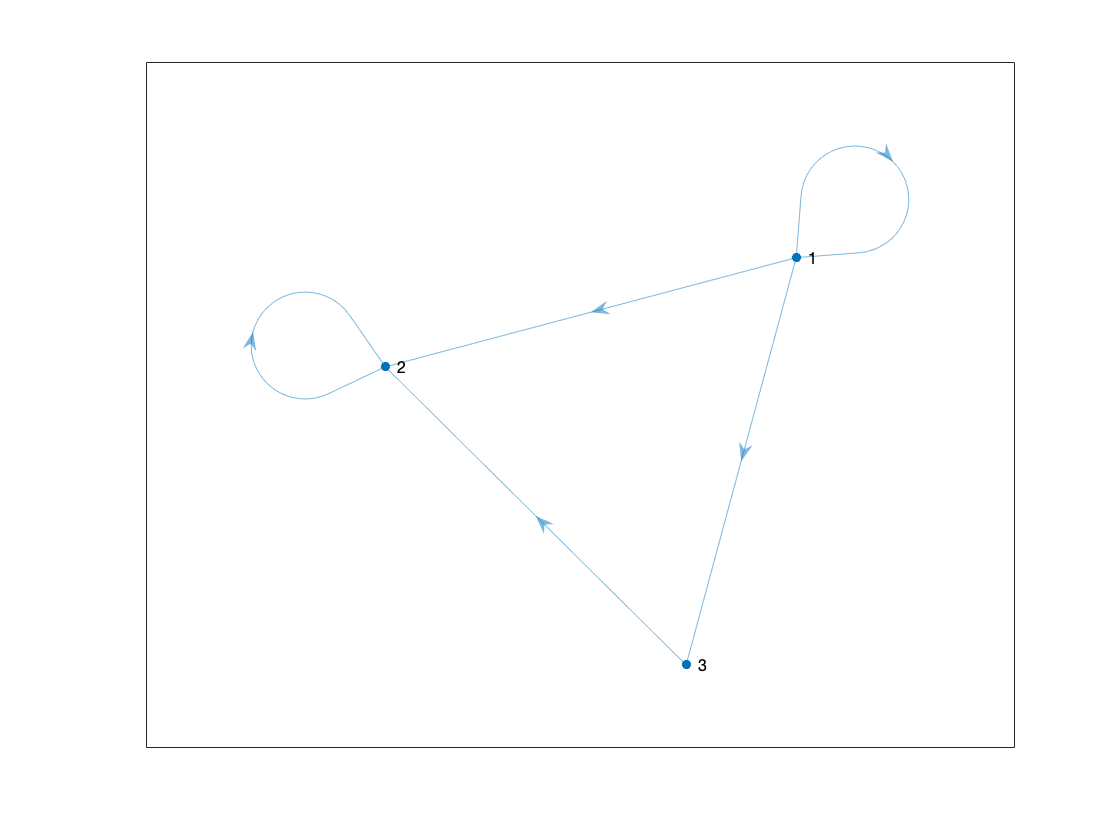

plot(DG)

Note that the two data structures appear the same, but MATLAB does treat them differently and has some distinct commands for dealing with the two of them. For example the function `degree` calculates the degree of a node in a graph, but does not work on digraph, which has separate functions `indegree` and `outdegree` that compute incoming and outgoing degrees. Let's look at the `Edges` component:

DG.Edges

ans = 5×1 table
    EndNodes
    ________

     1    1 
     1    2 
     1    3 
     2    2 
     3    2 


Both the `Edges` and `Nodes` components are defined as MATLAB `tables`. At this point the `Edges` component has one entry called `EndNodes`. The graph is a purely topological entity. The lengths of the displayed edges are arbitrary. The real usefulness of the data structure is that we can add additional data to both the edges and the nodes. For example we can associate the elements of a vector `L` to each edge, so long as `length(L) = length(EndNodes)`.

DG.Edges.L=[1;3;5;7;9];
DG.Edges

ans = 5×2 table
    EndNodes    L
    ________    _

     1    1     1
     1    2     3
     1    3     5
     2    2     7
     3    2     9


The Nodes table is initially empty

DG.Nodes


ans =

  3×0 empty table



but we can add data to each node in a similar manner.

DG.Nodes.mass = [1;4;9];
DG.Nodes

ans = 3×1 table
    mass
    ____

     1  
     4  
     9  


## Constructing the Quantum Graph

To create the quantum graph routines, I first created a quantum graph data class, which is built on top of the digraph class, and added appropriate data for quantum graph problems:

source=[1 1 2];
target=[1 2 2];
L = [2*pi,4, 2*pi];
Phi = quantumGraph(source,target,L);

There can be other fields associated with the quantum graph but these are either optional fields, or fields set to the default, and must be set in a slightly different way. 

Most of the information is associated with the edges

`L:` (required)the vector of lengths (if scalar than repeated)

`nx:` (optional) the number of discretization points on each edge (if scalar then the same value used on each edge)

`x` and `y`: (optional, created if nxVec is set) the independent and dependent variables on each edge. `y` is set to `NaN` on initialization. Only created if nxVec specified. If `length(nxVec)==1`, then it is interpreted as the density of discretizatio points per unit length

Phi.Edges

ans = 3×3 table
    EndNodes    Weight      L   
    ________    ______    ______

     1    1       1       6.2832
     1    2       1            4
     2    2       1       6.2832


There are two variables associated to the nodes:

`y`: the dependent variable

`robinCoeff`: optional the constant determining the Robin boundary condition used in the Laplacian and in interpolating `y` from the edges to the nodes. This optional argument defaults to zero, i.e. to Kirchoff/Neuman boundary conditions. May be specified as scalar or vector. At leaf nodes only, Dirichlet boundary conditions can be used. This is specificed by a `NaN`. Specifying `NaN` at a non-leaf node will return an error.

Phi.Nodes

ans = 2×1 table
    robinCoeff
    __________

        0     
        0     


The above quantum graph is suitable for running the secular determinant codes below. This symbolic calculation does not depend on a discretization. However if you want to do numerics, you will need to set up vectors of *x*- and *y*- values along each edge. This involves first defining a vector `nx` containing the number of x values along each edge (including the endpoints), and then calling the following two routines to set up fields to hold the independent and dependent coordinates. For now, only uniform discretizations are allowed  but in the future we will add support for Chebyshev discretizations. Note that if `nxvec` is specificed but `Discretization` is not, then `Discretization` defaults to `Uniform`. The general syntas is now

`dumbbell=quantumGraph(source,target,L,'Key1',value1, 'key2',value2,...)`

The three required input parameters must appear in that order, followed by the optional parameters, specified as key-value pairs, that can appear in any order. The optional arguments, for now, are

- `nxvec `(associated to edges)

- `robincoeff `(associated to nodes)

- `Discretization `(property of graph)

- `plotCoordinateFcn `(property of graph, allows overloading of `plot)`

In addition, there are methods to add or change these values. We 

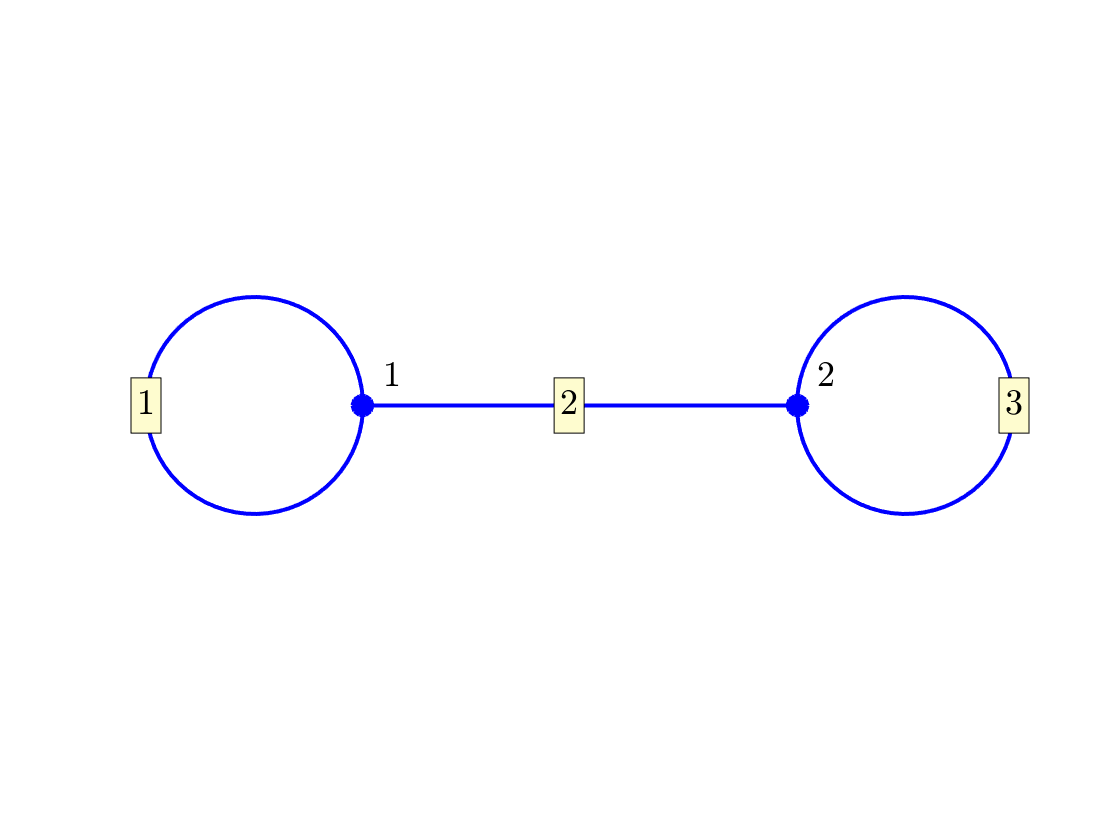

Phi=quantumGraph(source,target,L,...
             'Discretization','Uniform',...
             'nxvec',[63 20 63],...
             'plotCoordinateFcn',@dumbbellPlotCoords);
Phi.plot('layout')

The final name-value pair specifies the name of a user-defined function that sets up the coordinates and enables the plots of eigenfunctions given below. 

### Template functions

For many of our favorite graphs, we have created template functions, which are stored in the directory `source/templates`. All we need to do to create a dumbell matrix is to enter

Phi = dumbbell;

The template file contains default values for constructing the quantum graph. These can be overridden using key-value pairs.

## Computing with the quantum graph

Also included in the package are routines related to the Laplacian on the quantum graph. The discretized Laplacian is, of course, a matrix, and this is constructed directly from the quantum graph object. If the uniform discretization is specified, then the Laplacian matrix is defined when the quantum graph is initially constructed.

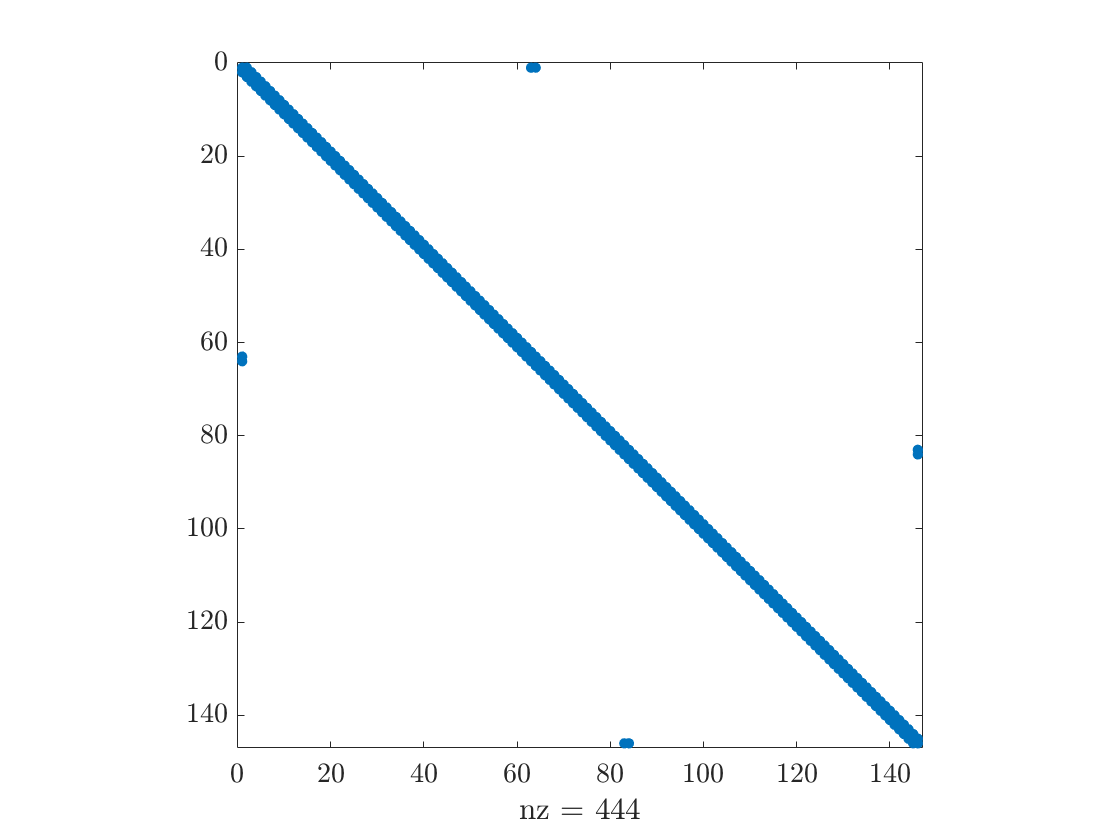

spy(Phi.laplacianMatrix)

If the Robin coefficients are zero, then the quantum graph Laplacian is self-adjoint, but you can see in the spy plot that the matrix constructed is not quite symmetric.

[V,lambda]=eig(Phi);

In the above calculation, a little cleanup needed because the null eigenvalue is sometimes is calculated as positive and sometimes as negative and this screws up the sorting. The line `d=-abs(d)` fixes this.

These eigenfunctions are all discretized as column vectors. The two functions `column2graph` and `graph2column` convert data back and forth between the column form and the full graph structure. There is no consistency checking in these programs, so user beware.

## First few eigenfunctions

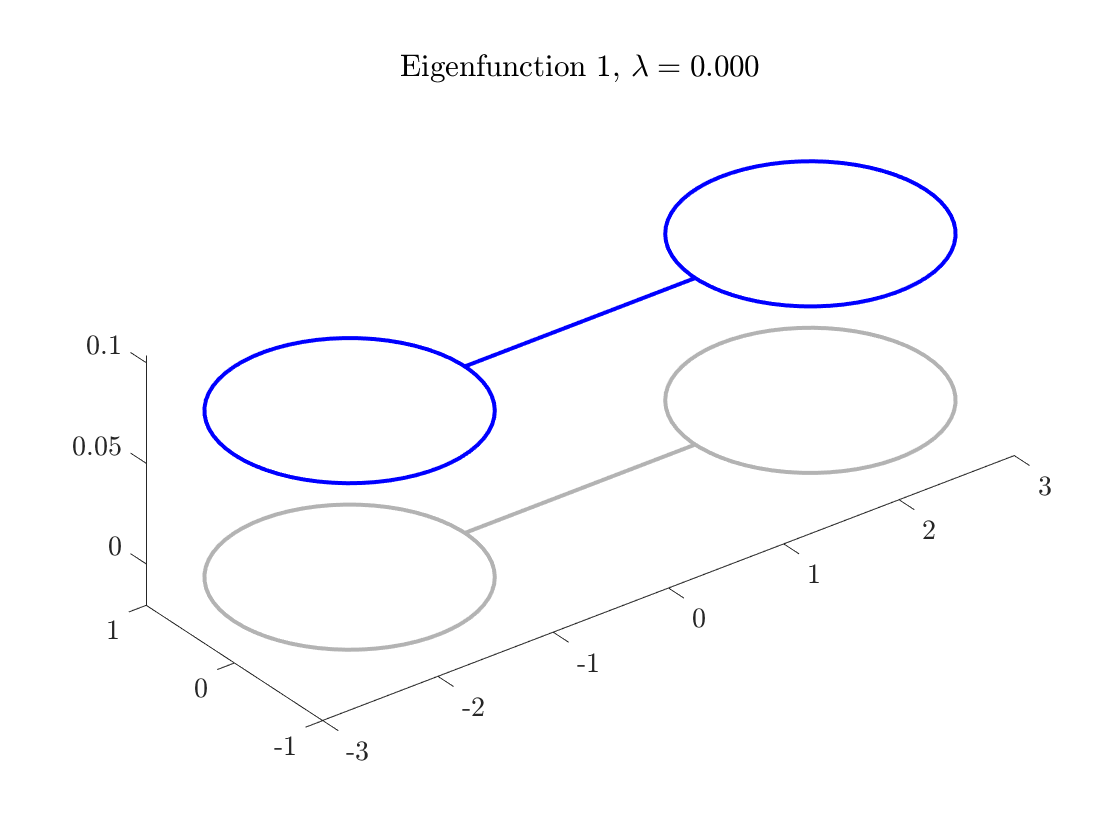

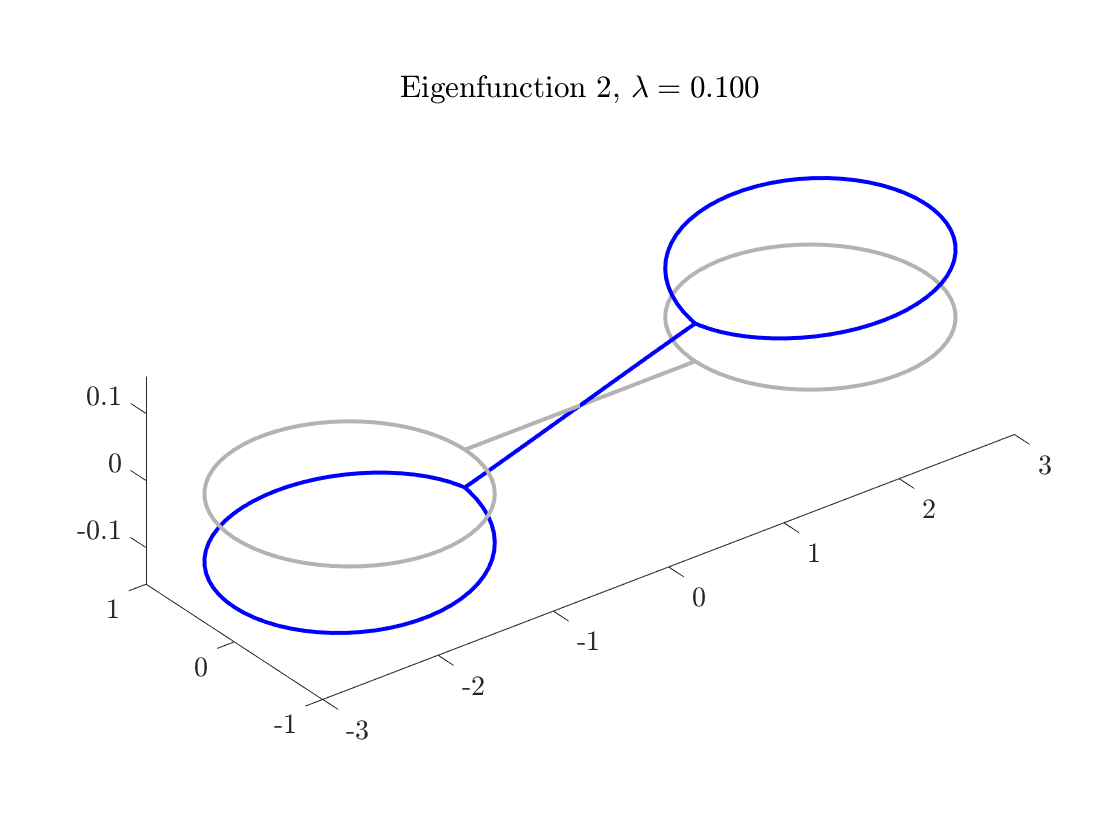

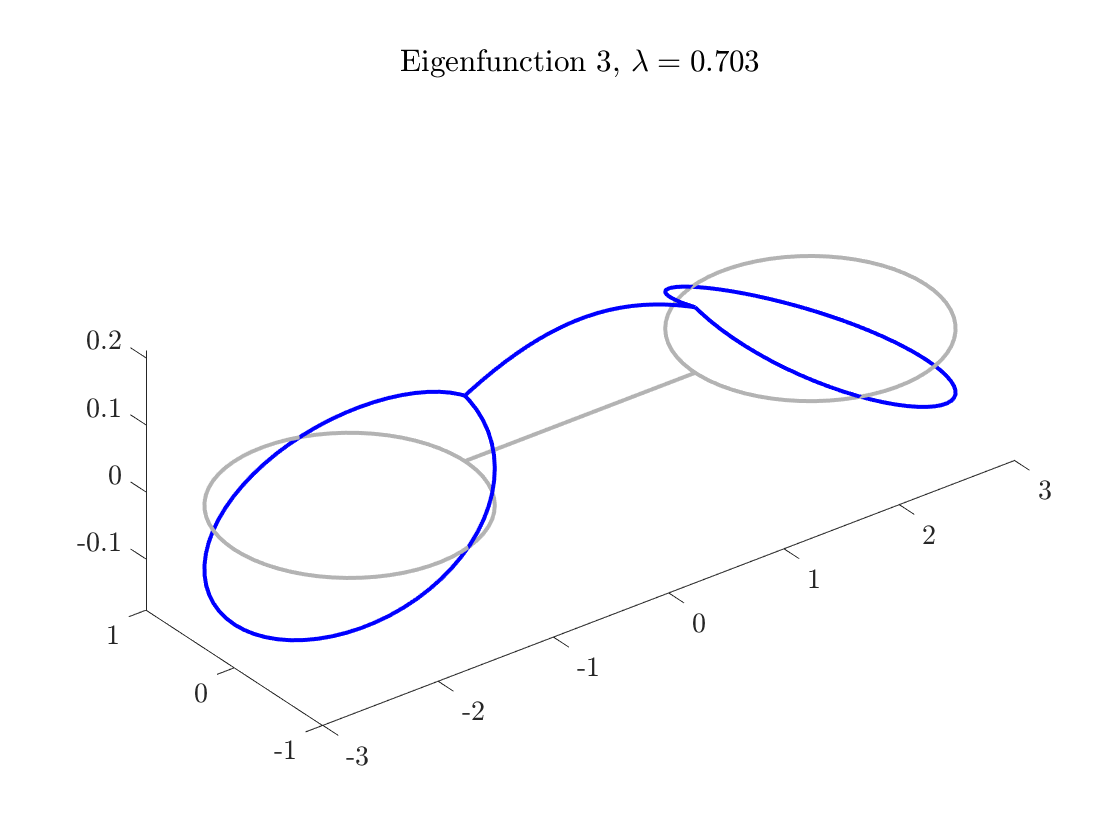

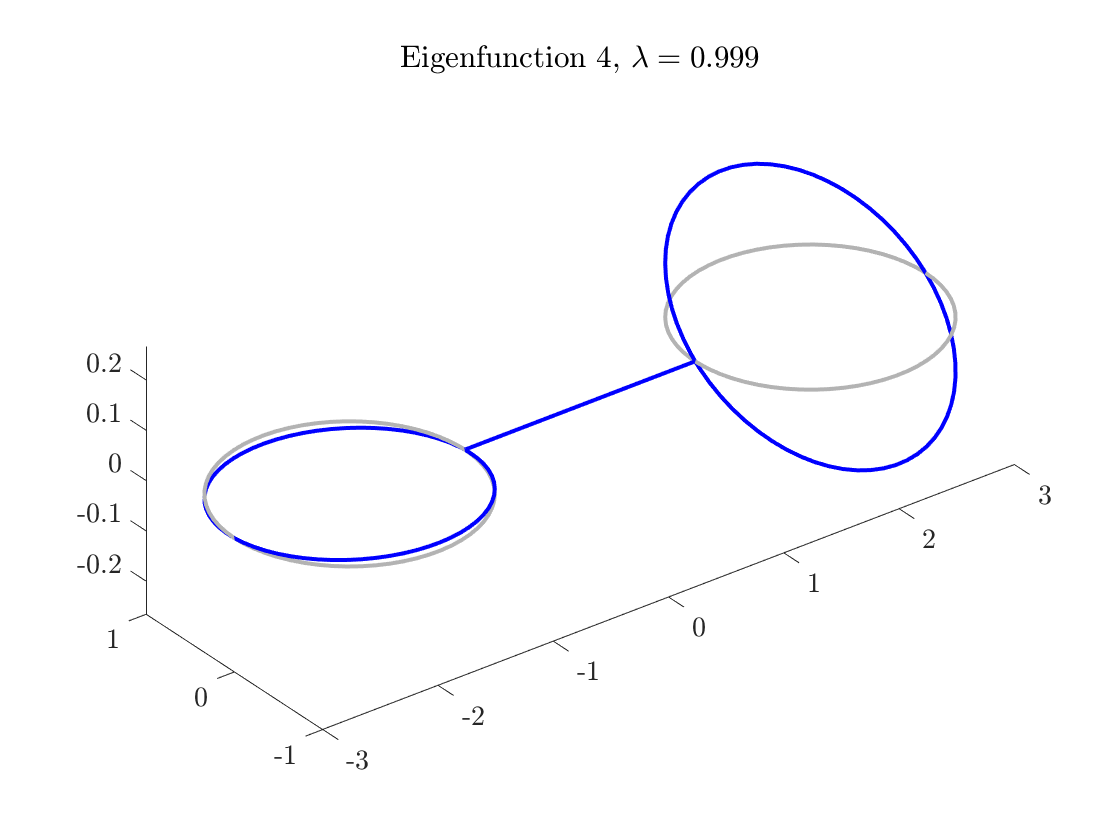

for k=1:4
    figure
    Phi.plot(V(:,k))
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$', k, lambda(k)));
end

## Graphs MATLAB Can't Work With (version 2017b and earlier).

Before version 2018a, Matlab's `digraph `structure could not handle multiple edges sharing the same source and target. Therefore a graph such as the *mandarin graph*, which has two vertices, and three separate edges connecting them cannot be represented.

The following will return an error in MATLAB versions older than 2018a.

source=[1 1 1 2]; target=[1 2 2 2];
quantumGraph(source,target,1);

**A simple fix.** In older versions, this gives an error because the second edge and the fourth are both $1 \to 2$. We can fix this by flipping the fourth edge to $2\to1$. 

source=[1 1 2 2]; target=[1 2 1 2];
g=quantumGraph(source,target,1);

This won't work for the mandarin graph. Instead, we can fix it by inserting additional nodes. The package will work fine this way, you just have to remember which nodes are real and which are simply there to distinguish edges. You may want to increase the number of grid points to keep the accuracy. The Kirchoff boundary condition applied to a vertex with two edges says merely that the function and its derivative are continuous across the boundary.

sMandarin=[1 1 1 2 3 4]; tMandarin=[2 3 4 5 5 5];
gMandarin=quantumGraph(sMandarin,tMandarin,1);

**This is not a problem since MATLAB 2018A **

The current edition can handle so-called *multigraphs.*

sMandarin=[1 1 1];tMandarin=[2 2 2];
gMandarin=quantumGraph(sMandarin,tMandarin,1,'nxVec',10);

## The secular determinant

The eigenvalues of quantum graph are given by $\lambda=-k^2$ where $k$ is a root of the secular determinant. The following code constructs the secular determinant as a symbolic expression $f(k)$. So far we have only implemented this for Kirchhoff boundary conditions but generalizations are coming.

f=secularDet(Phi)

$$f = -\frac{8\,\left(\cos\left(2\,\pi \,k\right)-1\right)\,\left(4\,\cos\left(2\,k\right)\,\sin\left(2\,\pi \,k\right)-3\,\sin\left(2\,k\right)+5\,\sin\left(2\,k\right)\,\cos\left(2\,\pi \,k\right)\right)}{9}$$

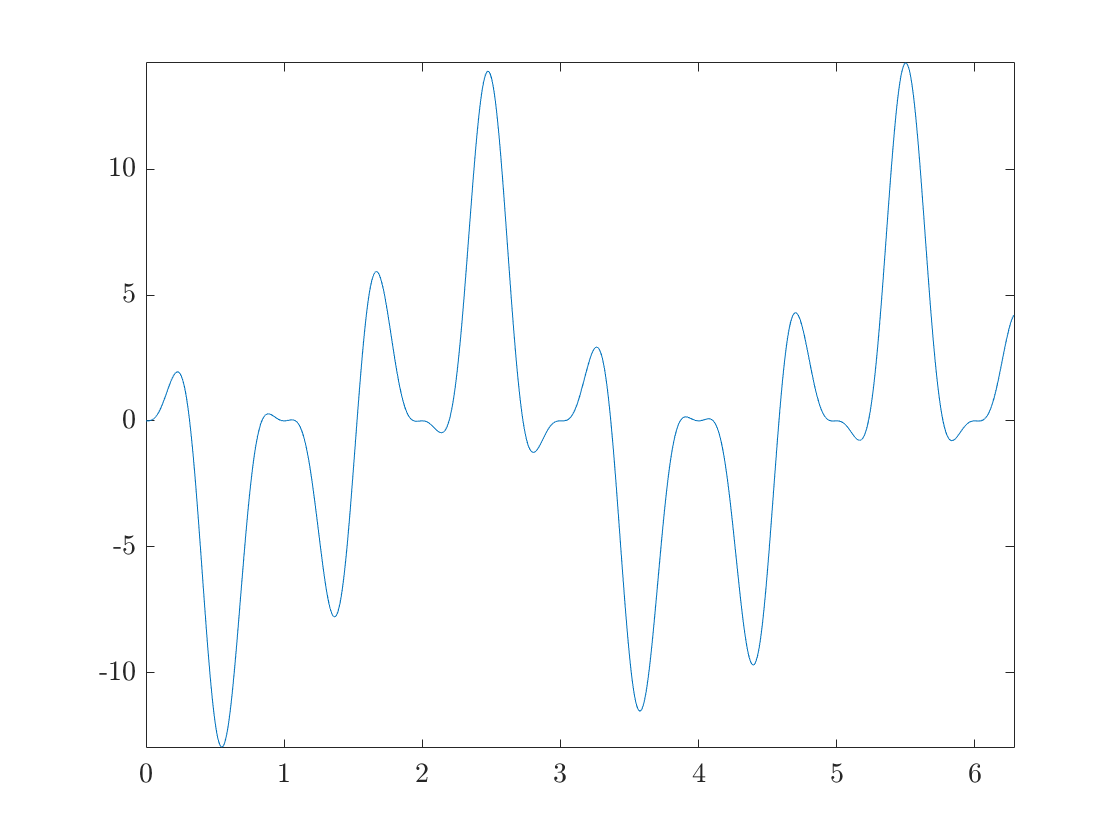

fplot(f,[0 2*pi])